# Part 1: Data Preparation and Feature Extraction

***Industrial Machinery Anomaly Detection***

# 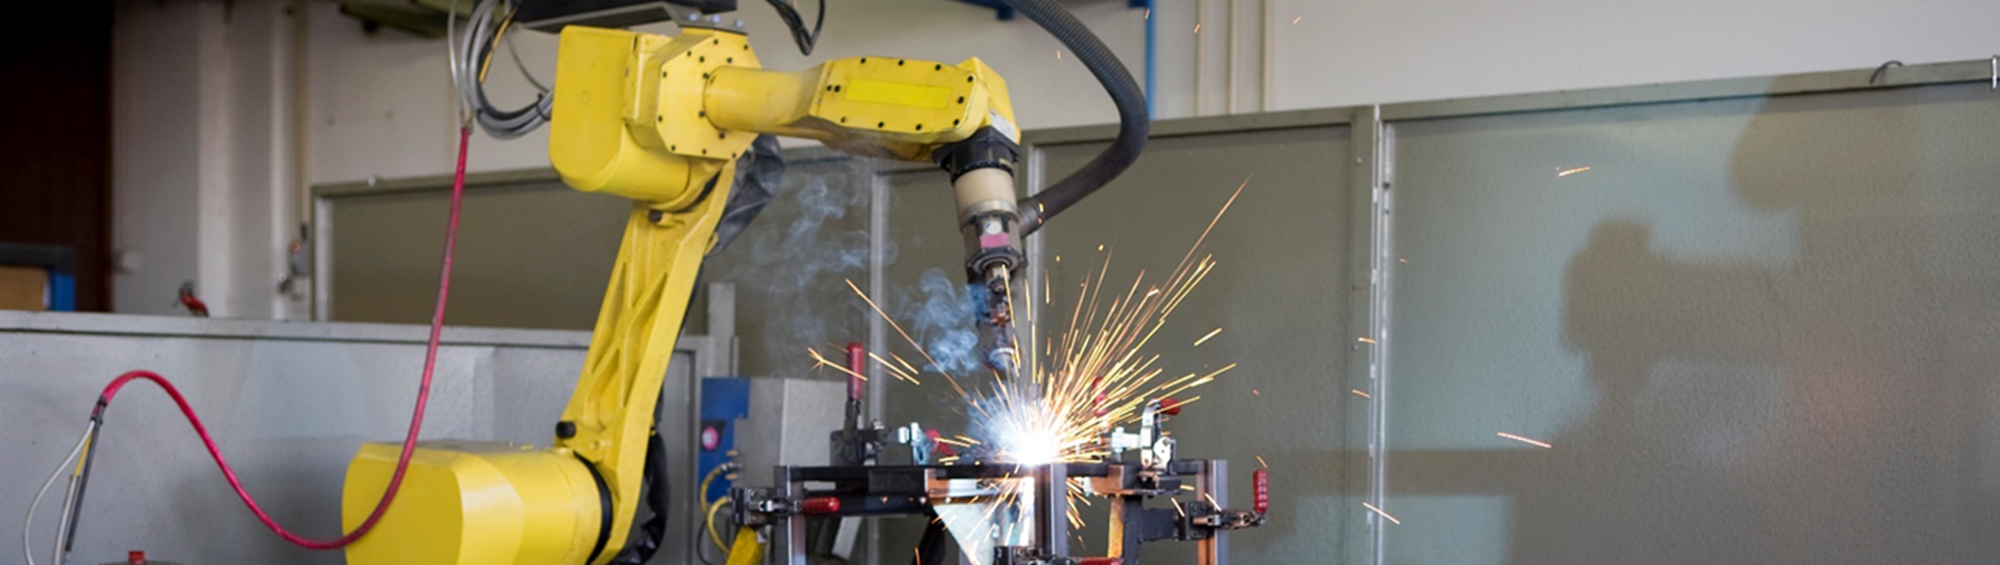

In this example, we train a bidirectional LSTM autoencoder to detect if a machine is working normally. An autoencoder is trained on a set of 12 features, extracted from healthy operating data collected from vibration sensors directly after a scheduled maintenance period. Features were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html)™.

We then use the trained model to reconstruct the features extracted from new data. If the model reconstructs the features well, it indicates that the machine is operating normally. If the reconstruction surpasses an error threshold, this indicates that the machine is acting abnormally and requires maintenance.

## Load Data

We have collected three-channel timeseries accelerometer signals from an industrial machine before and after scheduled maintenance periods. We can assume that since maintenance was (hopefully!) performed properly, that all of the "After" data is healthy. However, the "Before" data is less clear: the machine was may have been taken offline for maintenance due to a problem, but more often when performing scheduled maintenance machines are taken down even when they are operating normally. 

Start by loading in the dataset.

load("MachineData.mat")
trainData

trainData = 40×4 table
          ch1                 ch2                 ch3           label 
    ________________    ________________    ________________    ______

    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double}    Before
    {70000×1 double}    {70000×1 double}    {70000×1 double

## Visualize Data Before and After Maintenance

To better understand the data, let's visualize it before and after maintenance. If we move through each of the members, we see that the data before and after maintenance does look noticeably different.

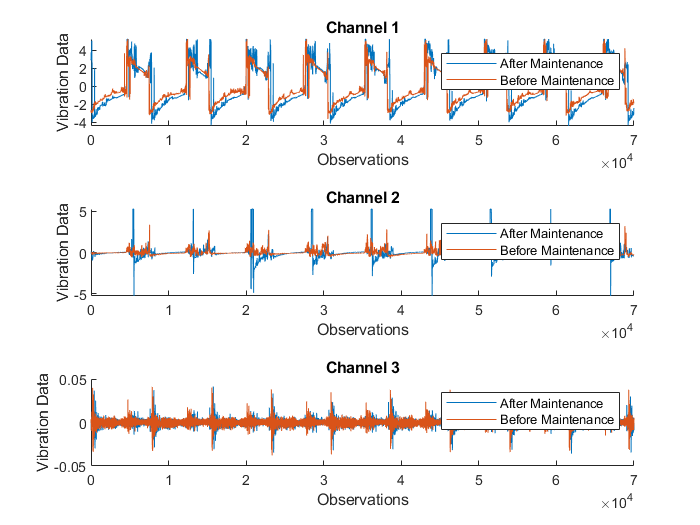

ensMember = 4;
plotVibrationData(trainData, ensMember)

## Extract Features with Diagnostic Feature Designer App

While it is possible to train a model on raw data, it is often better to extract relevant features to achieve the best accuracy. The [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the Predictive Maintenance Toolbox™ lets you interactively explore and preprocess your data, extract time- and frequency-domain features, then rank the features to determine which will be most effective. You can then automatically export a function to regenerate this work programmatically. 

The following command will bring up the app, or you can find it in the Apps tab. 

Before you import the data, be sure to set `label` as a **condition variable**. This is because the data label identifies the condition of the machine: before maintenance vs. after maintenance, and we can examine these datasets separately. The goal is to train a model to differentiate between these two conditions.

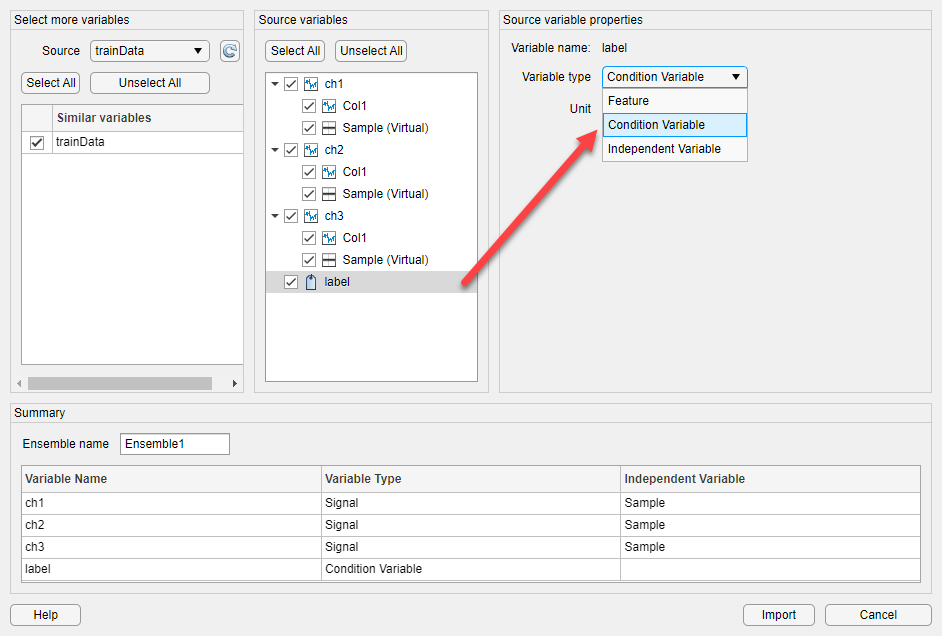

You can use the Diagnostic Feature Designer to iterate on the features and rank them. We'll use the top four ranked features for each channel.

- Ch1 : Crest Factor, Kurtosis, RMS, Std

- Ch2 : Mean, RMS, Skewness, Std

- Ch3 : Crest Factor, SINAD, SNR, THD

This visualization from the Diagnostic Feature Designer App shows the distributions separated by labels for various features extracted from Ch1 (Note: the histograms shown below are from a much larger version of this dataset, so the separation is more pronounced. The dataset included with this example is a subset of the original data, so you may end up with slightly different feature rankings).

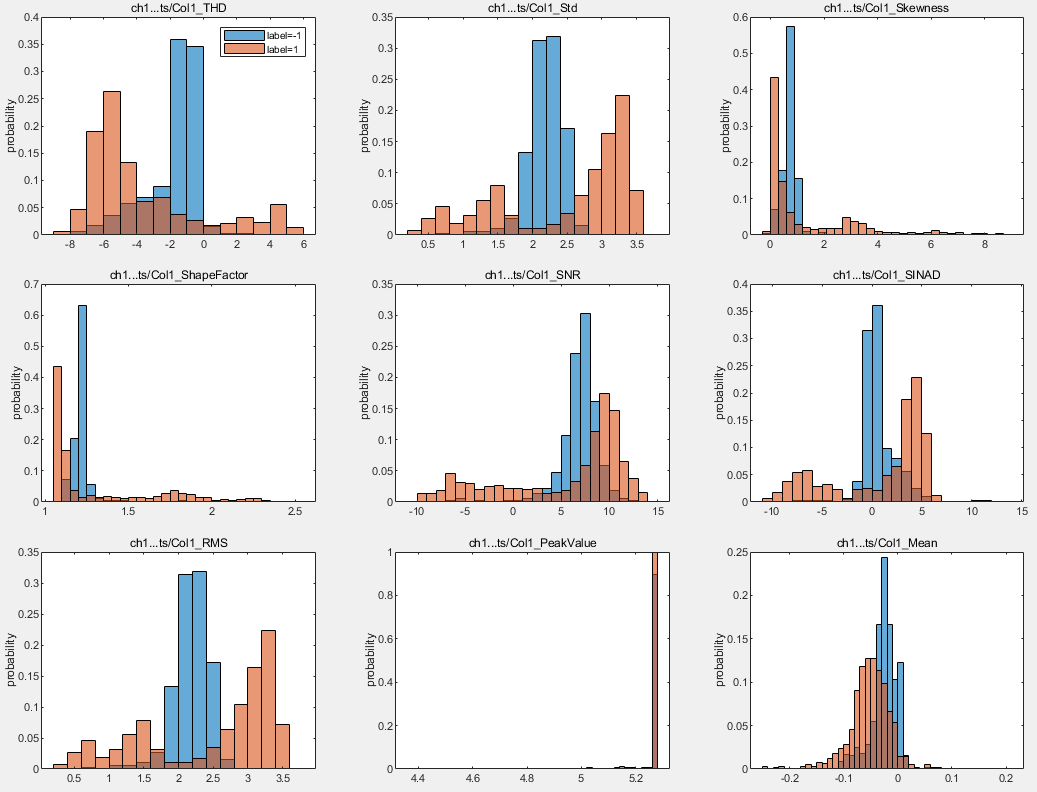

The `generateFeatures` function was created with the Diagnostic Feature designer app. It extracts the top 4 relevant features from each channel in the entire dataset, which we will use to train our biLSTM autoencoder in the next task.

trainFeatures = generateFeatures(trainData);

Copyright 2021 The MathWorks, Inc.